%Load reference path for recorded drive segment
%Loading Ego Vehicle set points
xData   = load('refPosesX.mat');
yData   = load('refPosesY.mat');
yawData = load('refPosesT.mat');
% Set up workspace variables used by model
refPosesX = xData.refPosesX;
refPosesY = yData.refPosesY;
refPosesT = yawData.refPosesT;
Ts = 0.21245;
%Setting up lidar parameters
Vfov= 1;
Vres = 1;
Hfov = 360;
Hres = 0.1;

%Open model and run it to store point cloud data
open_system('lidarStates');
%Run the model to save lidar data

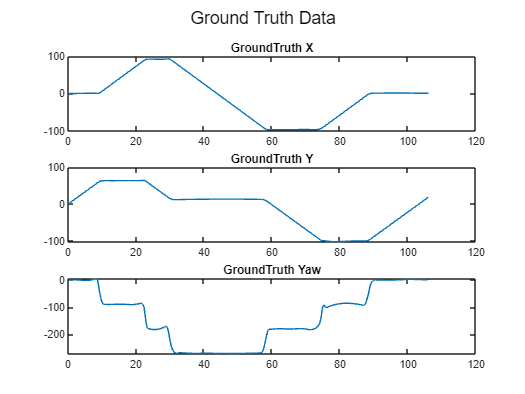

%Visualize groundtruth X, Y, and Yaw data.
t = xData.refPosesX(:,1); %Which is also consists of 500 element with deltaT = 0.21245(sec.)
refX = xData.refPosesX(:,2)+17.5109; %Plot X data starting from X(0) = 0
refY = yData.refPosesY(:,2)+11.1966; %Plot Y data starting from Y(0) = 0
refYaw = yawData.refPosesT(:,2)-89.6327; %Plot Yaw data starting from Yaw(0) = 0
figure;
%Creating subplots
subplot(3, 1, 1);
plot(t, refX);
title('GroundTruth X');

subplot(3, 1, 2);
plot(t, refY);
title('GroundTruth Y');

subplot(3, 1, 3);
plot(t, refYaw);
title('GroundTruth Yaw');
sgtitle('Ground Truth Data'); %Adding a title for all subplots

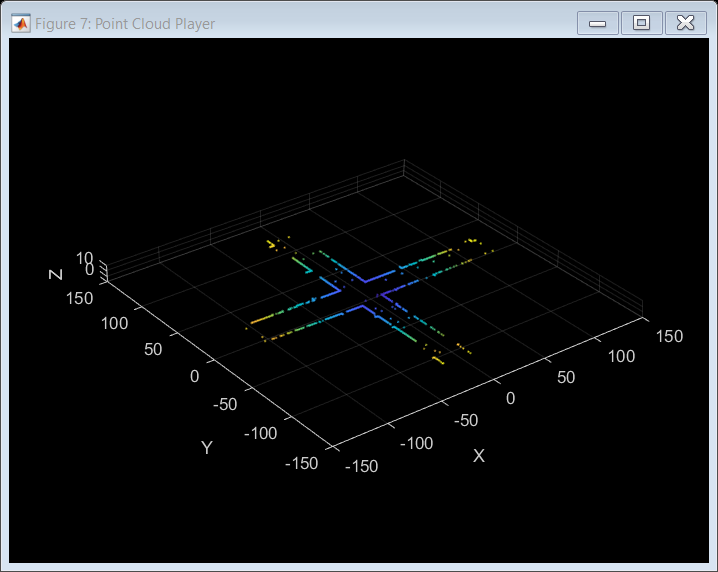

%Visualize point cloud data
xlimits = [-150 150];
ylimits = [-150 150];
zlimits = [ -5 10];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
pcdArray = squeeze(out.ptCloudData.signals.values);
for i = 1:size(pcdArray,3)
    pcdX = pcdArray(:,1,i);
    pcdY = pcdArray(:,2,i);
    pcdZ = pcdArray(:,3,i);
    point_cloud_data = [pcdX, pcdY, pcdZ];
    % Update the plot with the point cloud for the current frame
    view(player, point_cloud_data);
    pause(0.21245); % Adjust the pause duration as needed
end

X = zeros(1, size(out.ptCloudData.signals.values,4));
Y = zeros(1, size(out.ptCloudData.signals.values,4));
Yaw = zeros(1, size(out.ptCloudData.signals.values,4));
for i = 1:(size(out.ptCloudData.signals.values,4)-1)
    fixedPtc= out.ptCloudData.signals.values(:,:,:,i);
    tfPtc = out.ptCloudData.signals.values(:,:,:,(i+1));
    ptCloudOne = pointCloud(reshape(tfPtc, [], 3));
    ptCloudTwo = pointCloud(reshape(fixedPtc, [], 3));
    [tform, ~, ~] = pcregistericp(ptCloudOne, ptCloudTwo,'Extrapolate', true);
    % Extract rotation matrix and translation vector from transformation matrix
    R = tform.T(1:3, 1:3);
    eulerAngles = -rotm2eul(R, 'XYZ');
    deltaYaw_vehicle_deg = double(rad2deg(eulerAngles(3)));
    t = tform.T(4, 1:3)';
    deltaX_vehicle_m = - (t(1) * sin(deg2rad(Yaw(i)))) + (t(2) * cos(deg2rad(Yaw(i))));
    deltaY_vehicle_m = - (t(2) * sin(deg2rad(Yaw(i)))) + (t(1) * cos(deg2rad(Yaw(i))));
    X(i+1) = X(i) + deltaX_vehicle_m;
    Y(i+1) = Y(i) + deltaY_vehicle_m;
    Yaw(i+1) = Yaw(i) + deltaYaw_vehicle_deg;
end

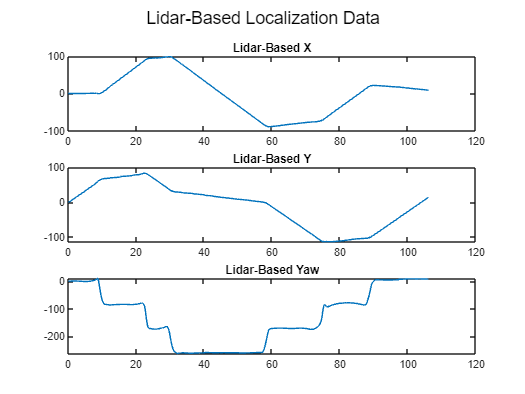

%Visualize Lidar-Based X, Y, and Yaw data.
%Creating subplots
t = xData.refPosesX(:,1);
subplot(3, 1, 1);
plot(t, X);
title('Lidar-Based X');

subplot(3, 1, 2);
plot(t, Y);
title('Lidar-Based Y');

subplot(3, 1, 3);
plot(t, Yaw);
title('Lidar-Based Yaw');

sgtitle('Lidar-Based Localization Data'); %Adding a title for all subplots

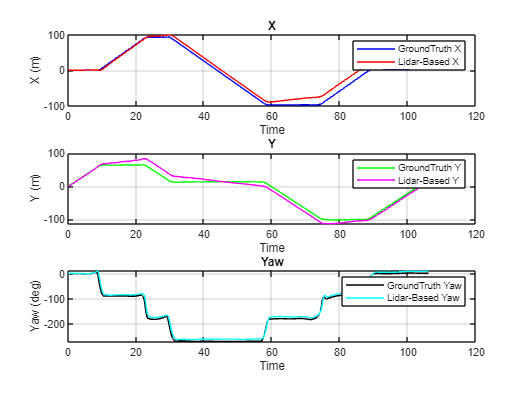

%plot both data together
figure;
% Subplot 1
subplot(3, 1, 1);
plot(t, refX, 'b', t, X, 'r');
title('X');
xlabel('Time');
ylabel('X (m)');
legend('GroundTruth X', 'Lidar-Based X');
grid on;
% Subplot 2
subplot(3, 1, 2);
plot(t, refY, 'g', t, Y, 'm');
title('Y');
xlabel('Time');
ylabel('Y (m)');
legend('GroundTruth Y', 'Lidar-Based Y');
grid on;

% Subplot 3
subplot(3, 1, 3);
plot(t, refYaw, 'k', t, Yaw, 'c');
title('Yaw');
xlabel('Time');
ylabel('Yaw (deg)');
legend('GroundTruth Yaw', 'Lidar-Based Yaw');
grid on;

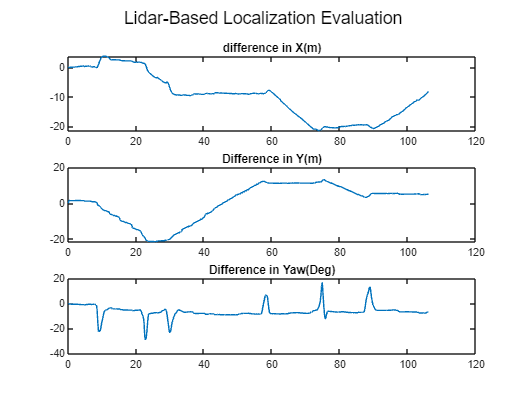

%Model Evaluation Based on difference between Lidar-Based data and
%groundtruth data
diffX = refX - X';
diffY = refY - Y';
diffYaw = refYaw - Yaw';
subplot(3, 1, 1);
plot(t, diffX);
title('difference in X(m)');

subplot(3, 1, 2);
plot(t, diffY);
title('Difference in Y(m)');

subplot(3, 1, 3);
plot(t, diffYaw);
title('Difference in Yaw(Deg)');

sgtitle('Lidar-Based Localization Evaluation'); %Adding a title for all subplots

%To compare with data estimated relying baesd on accurate INS System
XBar = zeros(1, size(out.ptCloudData.signals.values,4));
YBar = zeros(1, size(out.ptCloudData.signals.values,4));
YawBar = zeros(1, size(out.ptCloudData.signals.values,4));
for i = 1:(size(out.ptCloudData.signals.values,4)-1)
    fixedPtc= out.ptCloudData.signals.values(:,:,:,i);
    tfPtc = out.ptCloudData.signals.values(:,:,:,(i+1));
    ptCloudOne = pointCloud(reshape(tfPtc, [], 3));
    ptCloudTwo = pointCloud(reshape(fixedPtc, [], 3));
    [tform, ~, ~] = pcregistericp(ptCloudOne, ptCloudTwo,'Extrapolate', true);
    % Extract rotation matrix and translation vector from transformation matrix
    R = tform.T(1:3, 1:3);
    eulerAngles = -rotm2eul(R, 'XYZ');
    deltaYaw_vehicle_deg = double(rad2deg(eulerAngles(3)));
    t = tform.T(4, 1:3)';
    deltaX_vehicle_m = - (t(1) * sin(out.INSYaw.data(i)-(pi/2))) + (t(2) * cos(out.INSYaw.data(i)-(pi/2))); %-pi/2 to refrence it to zero
    deltaY_vehicle_m = - (t(2) * sin(out.INSYaw.data(i)-(pi/2))) + (t(1) * cos(out.INSYaw.data(i)-(pi/2))); %as if we are starting from zero yaw
    XBar(i+1) = XBar(i) + deltaX_vehicle_m;
    YBar(i+1) = YBar(i) + deltaY_vehicle_m;
    YawBar(i+1) = YawBar(i) + deltaYaw_vehicle_deg;
end

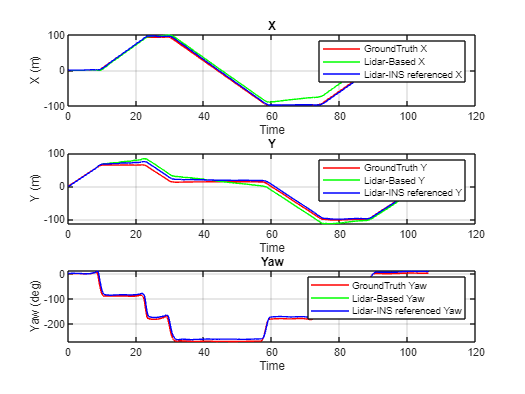

%plot both data together
t = xData.refPosesX(:,1);
figure;
% Subplot 1
subplot(3, 1, 1);
plot(t, refX, 'r', t, X, 'g', t, XBar, 'b');
title('X');
xlabel('Time');
ylabel('X (m)');
legend('GroundTruth X', 'Lidar-Based X', 'Lidar-INS referenced X');
grid on;

% Subplot 2
subplot(3, 1, 2);
plot(t, refY, 'r', t, Y, 'g', t, YBar, 'b');
title('Y');
xlabel('Time');
ylabel('Y (m)');
legend('GroundTruth Y', 'Lidar-Based Y', 'Lidar-INS referenced Y');
grid on;

% Subplot 3
subplot(3, 1, 3);
plot(t, refYaw, 'r', t, Yaw, 'g', t, YawBar, 'b');
title('Yaw');
xlabel('Time');
ylabel('Yaw (deg)');
legend('GroundTruth Yaw', 'Lidar-Based Yaw', 'Lidar-INS referenced Yaw');
grid on;

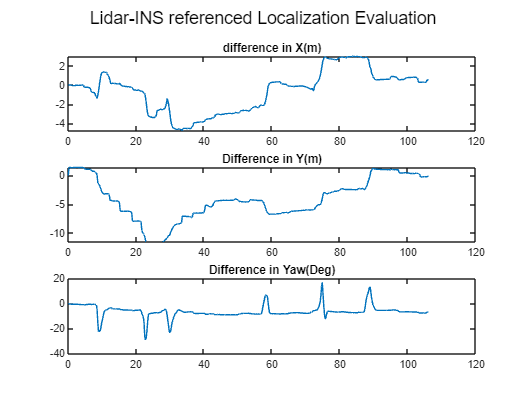

%Model Evaluation Based on difference between Lidar-INS referenced data and
%groundtruth data
diffX = refX - XBar';
diffY = refY - YBar';
diffYaw = refYaw - YawBar';
subplot(3, 1, 1);
plot(t, diffX);
title('difference in X(m)');

subplot(3, 1, 2);
plot(t, diffY);
title('Difference in Y(m)');

subplot(3, 1, 3);
plot(t, diffYaw);
title('Difference in Yaw(Deg)');

sgtitle('Lidar-INS referenced Localization Evaluation'); %Adding a title for all subplots